# Practical Session 2 - Pattern Recognition of Human Activities

## Introduction

In this practical session you will create a machine learning model to recognise the patterns of two activities of daily living: level-ground walking (LGW) and stair ascend (SA). The dataset for this session is a small portion of the dataset you will use for your assignment.

### Data Collection

The first step in every machine learning problem is to collect data. For this dataset, an Inertial Measurement Unit (IMU) was used to extract the accelerometer, gyroscope, and magnetometer values from various body parts, whilst performing LGW and SA. A total of **seven IMUs** are attached to different parts of the subject body (see figure below). In this version of the dataset, only the data for a single subject, and for a single IMU (Pelvis) is available. 

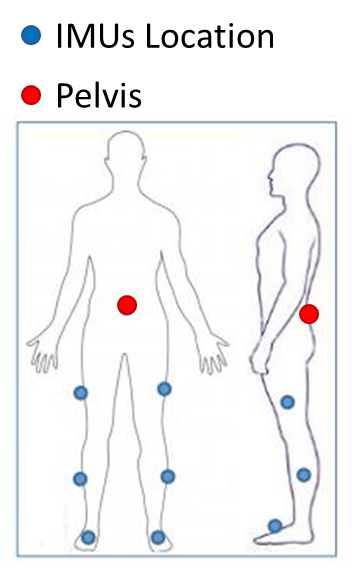

The IMUs capture a total of **nine** parameters. Below, there is an illustration  of the dataset structure used in here.

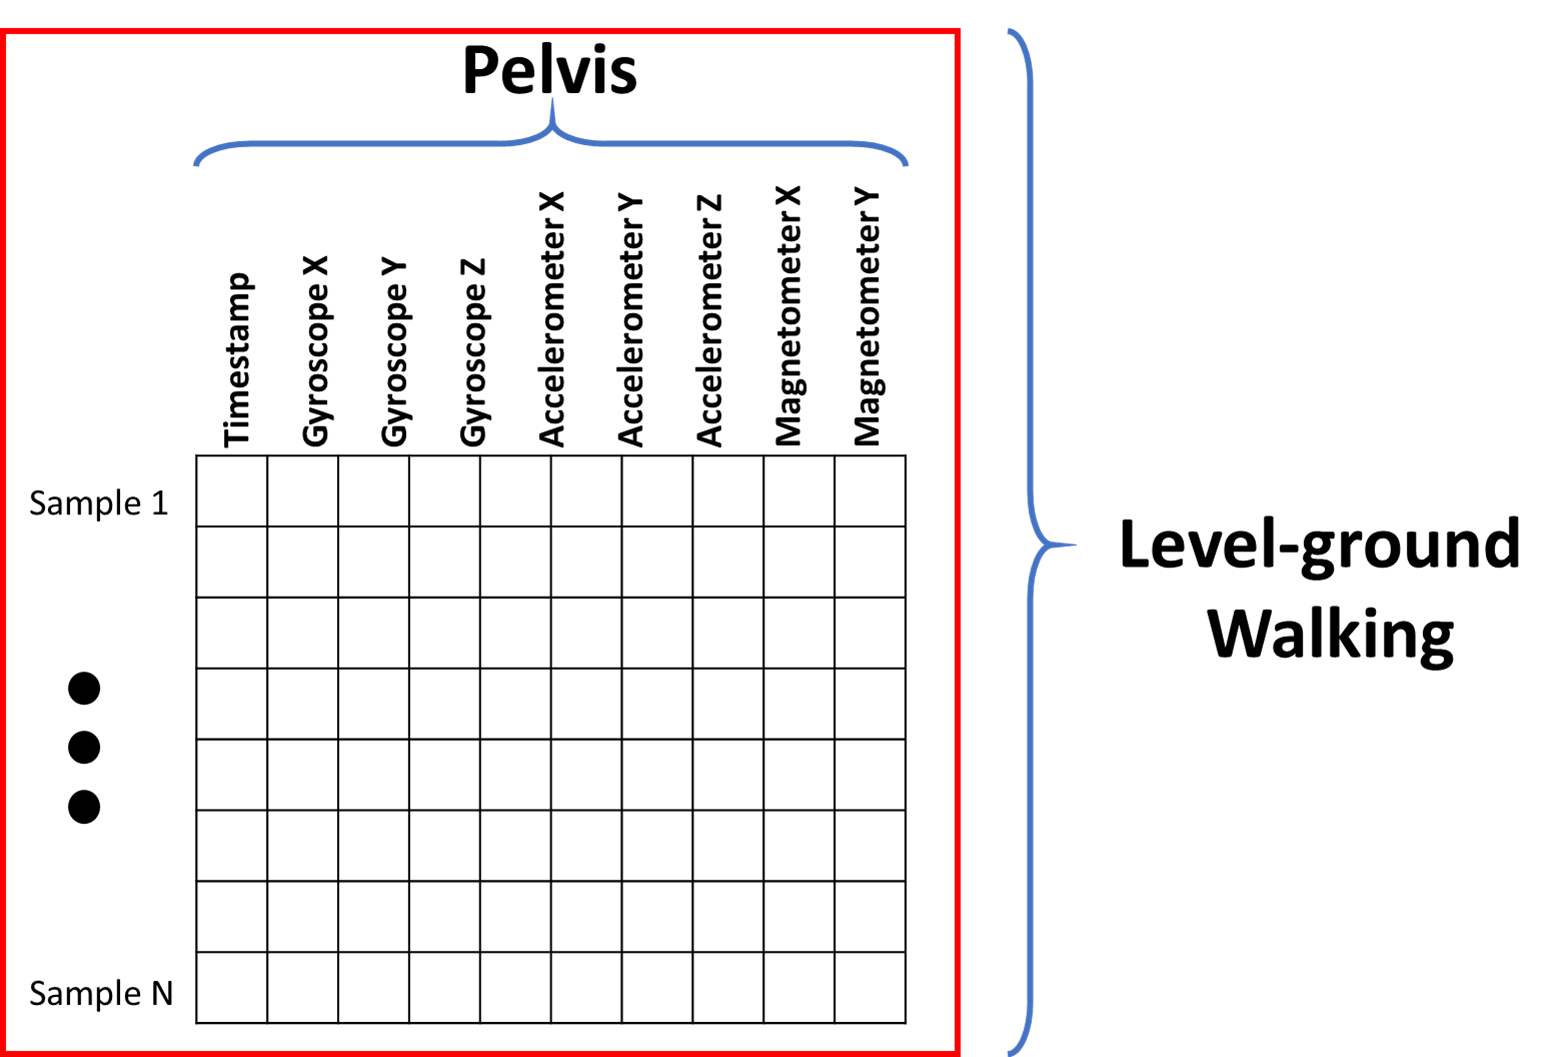

In this session you will work with two of these files, one for the LGW activity and one for the SA activity. Note that, as we are trying to classify which activity is being performed from the data. The activity type is the class which we will predict, just as last week the output of the logic gate was our class.

**A sanity check:**

You must use make sure that the mlx file you are currently working in is in the same "folder level" as the dat files you downloaded. You can do this by using the navigation panel on the right like so:

First click the browse for file button in the top-left of the screen, above "current folder". It looks like this:

Then select the folder that contains this mlx file and the .dat files you downloaded from Minerva.

Select the "LIVE EDITOR" panel at the top and click run section to run the following code:

%Load dataset into the workspace
clear;
clc;
close all;
rng(0);
LGW_Data = readtable("normal_walk_J_trial_01.dat","ReadVariableNames",true);
SA_Data = readtable("stair_asc_jun_trial_01.dat","ReadVariableNames",true);


### Data Preparation

Examine the previous variables (double click on them in the workspace on the right) to visualize the data arrangement. Then, run the following code to get just the "Pelvis" columns from both datasets.

%Extract pelvis data
dataRange = 61:70;
LGW_Pelvis = LGW_Data{:,dataRange};
SA_Pelvis = SA_Data{:,dataRange};

The above variables contain all the information from the Pelvic IMU which will be our **input dataset. **However, they do not have information regarding to which activity they belong to - our **target dataset**. This information must be added to the matrices above through a process called **encoding**. 

#### One Hot Encoding

**Encoding** is required when there is a mismatch  between the input dataset, which is **numerical**, and the target dataset, which is **categorical**. The categories must be represented by numbers. In the previous practical session, the cancer_dataset used a type of encoding called **One Hot Encoding. **

In this type of encoding, as many columns as there are target classes  are added to the input dataset. The numeric value of 1 indicates when a training sample (one row of data) belongs to a specific category. The numeric value of 0 indicates the opposite. This will become clear when you run this section and check what the data looks like in the workspace afterwards. This selection of values is better interpreted as probabilities, i.e. a 1 in a column means there is a 100% probability that it belongs to that class. We think of it this way because the model will output values between 0 and 1 and we have to choose a cutoff to round them to 0 and 1.

%Create an array of ones, and an array of zeros that matches the number of
%rows of each activity
%LGW Dataset
varLength = length(LGW_Pelvis);
var1 = ones(varLength,1);
var2 = zeros(varLength,1);
LGW_Pelvis_Full = horzcat(LGW_Pelvis,var1,var2);
%SA Dataset
varLength = length(SA_Pelvis);
var1 = ones(varLength,1);
var2 = zeros(varLength,1);
SA_Pelvis_Full = horzcat(SA_Pelvis,var2,var1);

Have a look at columns 11 and 12 in the LGW_Pelvis_Full and SA_Pelvis_Full variables. The first appended column represents the LGW class, and the second appended column represents the SA class in each variable. The complete training set can be form by vertically concatenating the variables LGW_Pelvis_Full and SA_Pelvis_Full. The last step of the **Data Preparation**  is to select the right features to train the machine learning model.

% Vertical concatenation
dataSet = vertcat(LGW_Pelvis_Full,SA_Pelvis_Full);

% Define which features to include in the input set.
inputs = dataSet(:,1:10)';
% inputs = dataSet(:,1:end-2);
% Define the target set
targets = dataSet(:,11:12)';
% targets = dataSet(:,end-1:end);

## Exercises

### Model Training

The function **patternnet() **is specialized for pattern recognition problems. We can create a Neural Network object by calling the patternnet function and giving it a vector containing the number of neurons and hidden layers. For example, If we state: **net = patternnet(10)**, we have created a neural network 'net' which contains 10 neurons in a single hidden layer. If we want multiple hidden layers, we can call **net = patternnet([10, 8, 6])** to create a model with 3 hidden layers that contain 10, 8, and 6 neurons. Feel free to research more about these functions in the Matlab Help Documentation: [https://www.mathworks.com/help/deeplearning/ref/patternnet.html;jsessionid=d93ee754eb74f86b825931cd15db.](https://www.mathworks.com/help/deeplearning/ref/patternnet.html;jsessionid=d93ee754eb74f86b825931cd15db.) 

Once we've created the network object 'net' above, we will give the model the entire dataset for training. But how do we specify how much of this data should be used to train, and how much should be used to validate and test? We do this by calling specifying the ratio of train and test data in the 'divideParam' part of the object, like so:

**net.divideParam.trainRatio = 70/100; **(note that you can just use 0.7 instead of 70/100)

**net.divideParam.valRatio = 15/100;**

**net.divideParam.testRatio = 15/100;**

This will change the internal properties of the 'net' object so that when we go to train it later, it already knows how much of the data to use for each of these steps.

Finally, we are then ready to train the model. We do this by calling: **[net,tr] = train(net,inputs,targets);**. This command calls the train() function and provides it with the network parameters, the input data, and the target data. The trained network will then be stored in 'net', and a new variable 'tr' will be created. 'tr' stores all of the information pertaining to the actual training process of the model, which we will cover later. Have a go at creating and training a model below!

#### **Task 1: Train a pattern recognition neural network**

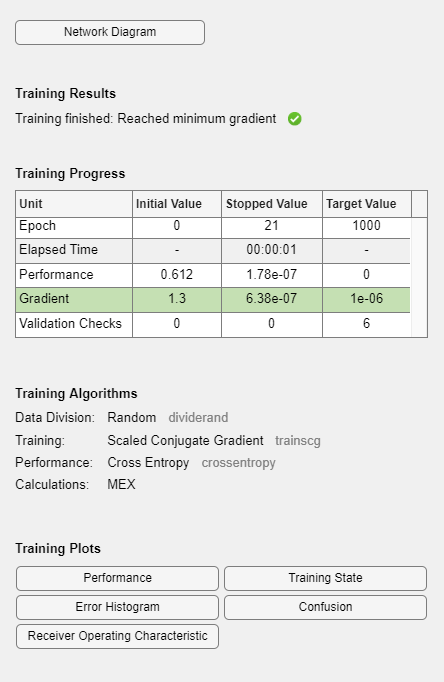

% Create a Pattern Recognition Network
net = patternnet(10);

% Set up Division of Data for Training, Validation, Testing Subsets
net.divideParam.trainRatio = 0.7;
net.divideParam.valRatio = 0.15;
net.divideParam.testRatio = 0.15;

% Train the Network
[net,tr] = train(net, inputs, targets);

### Model Evaluation

The next step is to evaluate the performance of this model under different scenarios.

#### **Task 2.1: Evaluate the performance of your model using **`dataSet`

The training set stored in the variable `dataSet` was split into a training, validation, and testing subset. During training, each subset has its unique role. The training subset is used to obtain the error between the model prediction and the target value. The validation subset is used to tune the weights and biases of the neurons inside the neural network with the aim of reducing the difference between the model prediction and the target value. The test subset is used to stop the training session when the error obtained during validation keeps decreasing but the error obtained during testing starts to increase. The latter method is called **Early Stopping,** and prevents the machine learning model to memorize the pattern from the training subset. We call this phenomenon **overfitting.**

A simple way to evaluate the performance of a machine learning model is by using the test subset, since it's the only portion of data not 'seen' by the network in the model training process. However, to get the training samples we need to know which samples the network chose to be used for training. We can do this with the 'tr' object we created during training. **tInd = tr.testInd;** Will get all the indices of the test data and store them. We can then use the location of these in our input set to ask the model to make predictions using just these test values with the following command:** tstOutputs = net(inputs(:,tInd)); **(note that calling **net(values)** returns the prediction of the model when 'values' is the input). We can then use the **perform()** and **plotconfusion()** functions to obtain our performance plots and confusion matrices, as we did last week.These are used in the following context: **tstPerform = perform(net,targets(:,tInd),tstOutputs) **and **figure, plotconfusion(targets(:,tInd),tstOutputs);.**

Have a go at using these 4 commands below and check out the plots they generate!.

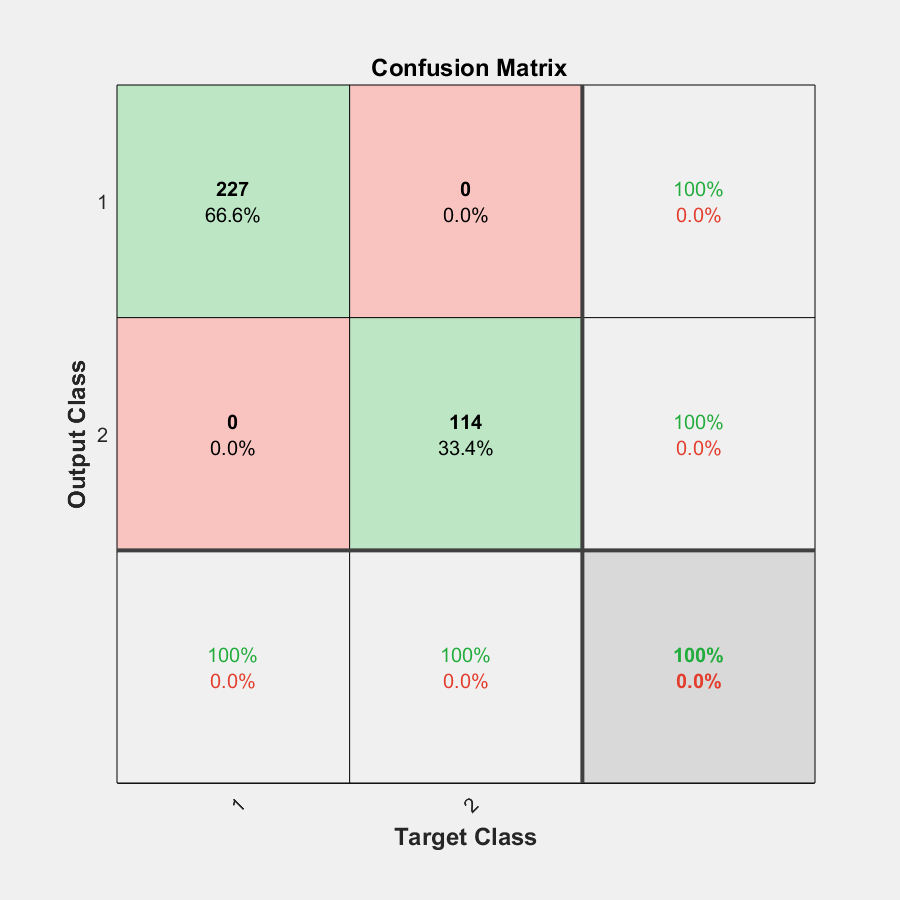

% Test the Network with the test subset from the current dataset
tInd = tr.testInd;
tstOutputs = net(inputs(:,tInd));

tstPerform = perform(net, targets(:,tInd), tstOutputs);
figure, plotconfusion(targets(:,tInd), tstOutputs);

disp(tstPerform)

   2.0638e-07



Remember that a 100% accuracy might indicate **overfitting, **and means that the model is likely to perform poorly when new data is presented to it because it has memorized the data used during training.

#### **Task 2.2: Evaluate the performance of your model using a new dataset**

A more robust approach to test the model performance is to use a completely new dataset which is unknown to the machine learning model. Therefore, in this task you should use the collected data from a different subject with the following files:

- normal_walk_lg_trial_01.dat

- stair_asc_lg_trial_01.dat

Use the previous examples and tasks to create a model and** train it on 100% of the data from normal_walk_J_trial_01.dat and stair_asc_jun_trial_01.dat. **Then, use the **net() **function with the new files to get predictions for the new data. Plot confusion matrices and performace plots as before and see what the accuracy looks like on the exact same activity, but with different people.

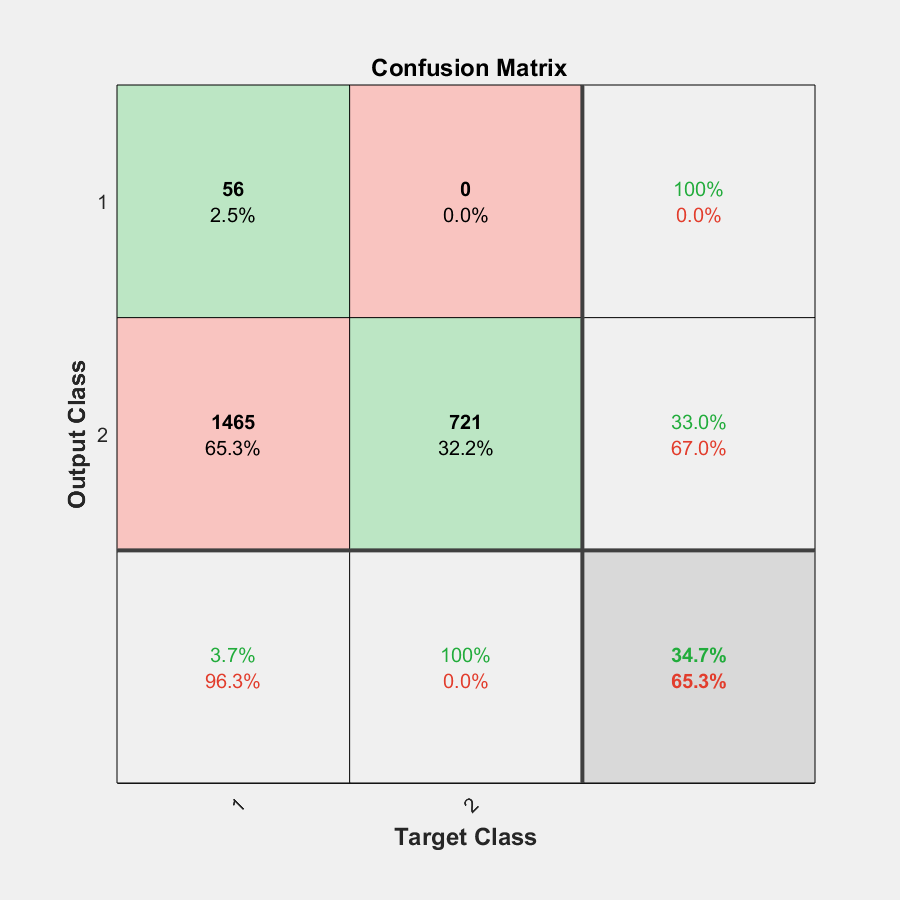

% Load data
Test_LGW_Data = readtable("normal_walk_lg_trial_01.dat","ReadVariableNames",true);
Test_SA_Data = readtable("stair_asc_lg_trial_01.dat","ReadVariableNames",true);

% Data Preparation
% Select Pelvis data
dataRange = 61:70;
Test_LGW_Pelvis = Test_LGW_Data{:,dataRange};
Test_SA_Pelvis = Test_SA_Data{:,dataRange};
%Create an array of ones, and an array of zeros that matches the number of
%rows of each activity
%LGW Dataset
Test_varLength = length(Test_LGW_Pelvis);
var1 = ones(Test_varLength,1);
var2 = zeros(Test_varLength,1);
Test_LGW_Pelvis_Full = horzcat(Test_LGW_Pelvis,var1,var2);
%SA Dataset
Test_varLength = length(Test_SA_Pelvis);
var1 = ones(Test_varLength,1);
var2 = zeros(Test_varLength,1);
Test_SA_Pelvis_Full = horzcat(Test_SA_Pelvis,var2,var1);

% Extract the new datasets
% Vertical concatenation
Test_dataSet = vertcat(Test_LGW_Pelvis_Full,Test_SA_Pelvis_Full);

% Format test data
% Define which features to include in the input set.
Test_inputs = Test_dataSet(:,1:10)';
% Define the target set
Test_targets = Test_dataSet(:,11:12)';

% Test the Network
% Test the Network with the test subset from the current dataset
Test_tstOutputs = net(Test_inputs);

tstPerform = perform(net, Test_targets, Test_tstOutputs);
figure, plotconfusion(Test_targets, Test_tstOutputs);

disp(tstPerform)

    5.8581



A bad accuracy can be an indicator of **overfitting. **Simple actions can be taken to minimize the risk of overfitting, such as: 

- reducing the number of, or changing, features used for training.

- reducing the number of neurons in the model.

- Increasing the diversity and quantity of the input data.

We will explore this in the next section.

### Feature Engineering

Feature Engineering is a method used to enhance the "meaning" of the data contained in a training set. A common approach is to calculate statistical parameters such as the mean, median, standard deviation, etc using a sliding window.

Feature Engineering is particularly useful for large datasets. Nonetheless, the feasibility of this approach is dependent on the application. In pattern recognition, statistical parameters can help machine learning models to learn complex pattern in less time.

**Task 3: Extract the moving average of each feature under k windows to train the model**

In this task, you will calculate the moving average of each feature on `inputs `using with a sliding window of 10 data points (k=10). This can easily be done with the function `movmean(). `Read the help documentation of this function to understand its functionality: [https://www.mathworks.com/help/matlab/ref/movmean.html.](https://www.mathworks.com/help/matlab/ref/movmean.html.) **You will then use these features instead of the raw data** to train and evaluate a pattern recognition model. 

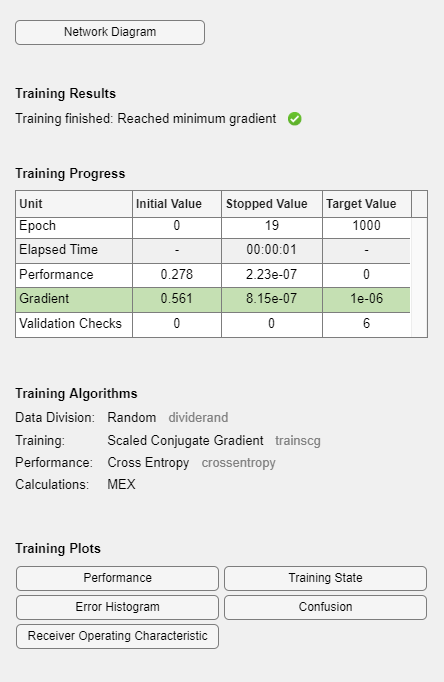

% Calculate the moving average values over a sliding window of size k 
% from each feature from each activity
k = 10;
lgw_pelvis_full_mean = movmean(LGW_Pelvis_Full, k);
sa_pelvis_full_mean = movmean(SA_Pelvis_Full, k);

% Create new input set
data_set_mean = vertcat(lgw_pelvis_full_mean, sa_pelvis_full_mean);
inputs_mean = data_set_mean(:, 1:10)';
outputs_mean = data_set_mean(:, 11:12)';

% Create a Pattern Recognition Network
net = patternnet(10);

% Set up Division of Data for Training, Validation, Testing Subsets
net.divideParam.trainRatio = 0.7;
net.divideParam.valRatio = 0.15;
net.divideParam.testRatio = 0.15;

% Train the Network
[net, tr] = train(net, inputs_mean, outputs_mean);



% Test the Network with the test subset from the current dataset
tstIndecies = tr.testInd;
tstOutputs = net(inputs_mean(:, tstIndecies));

tstPerform = perform(net, inputs_mean(:, tstIndecies), tstOutputs);

Error using bsxfun
Non-singleton dimensions of the two input arrays must match each other.

Error in gsubtract>calc_general (line 40)
    c = bsxfun(@minus,a,b);

Error in gsubtract>calc_cell (line 60)
  for i=1:numel(a), c{i} = calc_general(a{i},b); end


figure, plotconfusion(net, inputs_mean(:, tstIndecies), tstOutputs);

## Self-study

This practical session is directly related to your assignment. Therefore, be sure to explore this code as much as you can. Recommended tasks:

- Research about a different data division approach, different than the one used in here

- Visually analyse the features contained in the dataset for both activities by plotting each one of them against time. This can help you identify features that are similar among activities. In a scenario like this, extracting statistical parameters will help the machine learning model to correctly identify each pattern.

- Train the pattern recognition model using different combination of features to identify the most relevant

- Train the model using different parameters, such as number of neurons and stopping conditions

- Apply the sliding moving average of size **k** every **n** points, make **n<k**. This will create an array of **n** mean values. Reducing the size of the training ser is something you will use in your assignment.

Solutions will be made available after the session. Please let me know if you need assistance during or after the session.

## Credits

Made by Rodrigo Daniel Solis Ortega, adapted, updated and modified by Johnny Mitchell

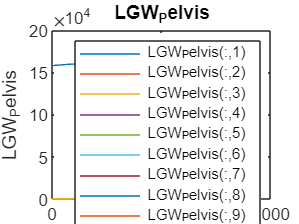

% Create plot of LGW_Pelvis
h = plot(LGW_Pelvis,"DisplayName","LGW_Pelvis");

% Add ylabel, title, and legend
ylabel("LGW_Pelvis")
title("LGW_Pelvis")
legend